T_jets=parquetread('jets_train.parquet.gzip');

%T_jets=parquetread('jets_test.parquet.gzip');

T_jets = movevars(T_jets,'is_signal_new','Before','E_0');
T_jets = sortrows(T_jets,'is_signal_new'); 
G = groupsummary(T_jets,'is_signal_new')

G = 2×2 table
    is_signal_new    GroupCount
    _____________    __________

          0            15068   
          1            14932   


Jet=Jet_Table_To_Jet_Tensor(T_jets);
pT=sqrt(Jet(:,2,:).^2+Jet(:,3,:).^2);         % transverse momentum of jet constituents
eta=squeeze(asinh(Jet(:,4,:)./pT));           % pseudorapidity tensor eta with 35 rows and 30k columns
phi=squeeze(atan2(Jet(:,3,:),Jet(:,2,:)));    % azimuth tensor phi with 35 rows and 30k columns

JetLabels

eta = eta - eta(1,:);        % this and line below: centering the hardest jet constituent in (eta,phi) grid
phi = phi - phi(1,:);        % jet constituent with the largest pT will have eta=phi=0  

Nb=37;                                 % number of buckets for eta and phi  
Xedges=linspace(-1.6,1.6,Nb+1);        % edges for buckets for eta. Nb+1 edges means Nb buckets 
Yedges=linspace(-1.6,1.6,Nb+1); 

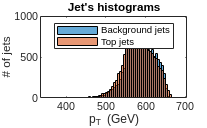

P=squeeze(sum(pT,1));                  % total transverse momentum of a jet
clf;
histogram(P(1:G{1,2}));                % distribution of transverse momenta of background jets
hold on
histogram(P(G{1,2}+1:end));            % distribution of transverse momenta of top jets
title("Jet's histograms")
legend({'Background jets','Top jets'},'Location','best')
xlabel("p_T (GeV)")
ylabel("# of jets")
hold off

xGrp = discretize(eta,Xedges);    % xGrp is same size as eta: 35x30k. Instead of eta values, xGrp contains bucket numbers for that values of eta
yGrp = discretize(phi,Yedges);    % yGrp is same size as phi: 35x30k. Instead of phi values, yGrp contains bucket numbers for that value of phi
zGrp = repelem(1:size(Jet,3),size(eta,1));       % zGrp is a row vector with 35*30k elements: 1,1,1..., 2,2,2..., 30k,30k,30k... 
V = rmmissing([pT(:) xGrp(:) yGrp(:) zGrp(:)]);  % remove rows with missing entries from a matrix V with 4 columns 
I = accumarray(V(:,2:4), V(:,1), [Nb, Nb, size(Jet,3)]);

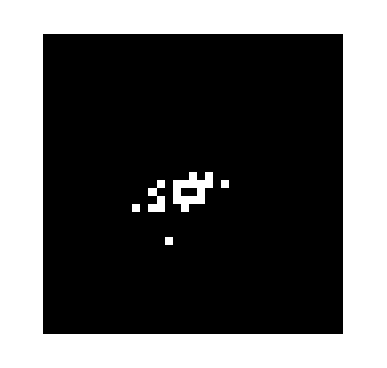

imshow(I(:,:,1))
truesize([300, 300]) 

imwrite(I(:,:,1),"example.png");

Ia=zeros(Nb^2,size(Jet,3));
parfor n=1:size(Jet,3)
    Ia(:,n)=reshape(I(:,:,n),Nb^2,1);
    Ia(:,n)=circshift(Ia(:,n),ceil(length(Ia(:,n))/2)-find(Ia(:,n)==max(Ia(:,n)))); % maximum of I will be centered       
end
Ia=normalize(Ia,'norm');            % normalize each column of Ia
I=reshape(Ia,Nb,Nb,[]);

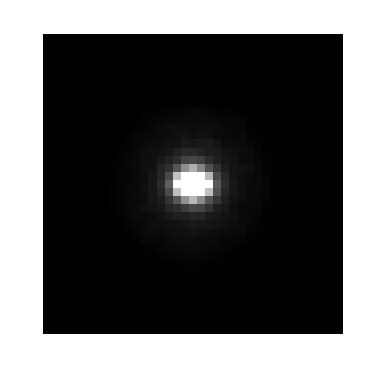

I_b=sum(I(:,:,1:G{1,2}),3)/200;      % sum all background jets
I_t=sum(I(:,:,G{1,2}+1:end),3)/200;  % sum all top jets
imshow(I_b)
truesize([300, 300]) 

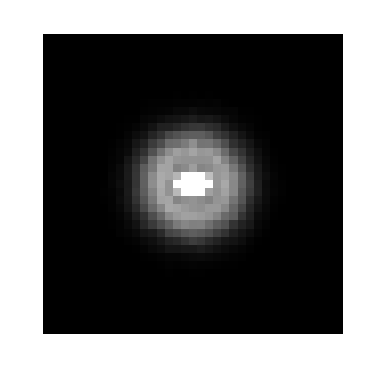

imshow(I_t)
truesize([300, 300]) 

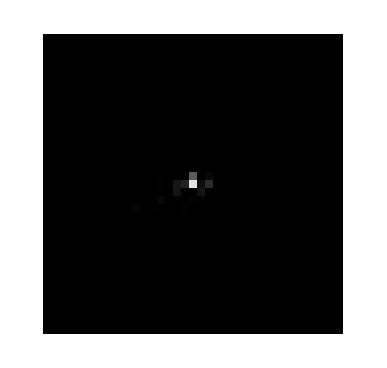

imshow(I(:,:,1))
truesize([300, 300]) 

imwrite(I(:,:,1),"example_after_normalization.png");

sz=size(I);
nsamples = sz(3)

nsamples = 30000

tab = table;
for i=1:nsamples
  mat = I(:,:,i);
  nonzero_rows = single([]);
  nonzero_cols = single([]);
  track_pt = single([]);
  for r=1:37
    for c=1:37
      has_nonzero = false;
      for k=1:1
        if mat(r,c,k) > 0.001
          has_nonzero = true;
        end
      end
      if has_nonzero
        nonzero_rows = [nonzero_rows; r];
        nonzero_cols = [nonzero_cols; c];
        track_pt = [track_pt; mat(r,c,1)];
      end
    end
  end
  row = nonzero_rows;
  col = nonzero_cols;  
   
  kvalue = 3;
  knns = knnsearch([row,col],[row,col],'K',kvalue+1,'Distance','Euclidean');
  A = zeros(length(knns),'int8');
  if length(knns) <= kvalue
    continue;
  end
  for n=1:length(knns)
    for m=2:kvalue+1
      A(knns(n,1),knns(n,m)) = 1;
    end
  end
  A = A + eye(size(A),'int8');
  
  clear newtab;
  newtab = table;
  newtab.Features = {track_pt};
  newtab.Adjacency = {A};
  newtab.y = T_jets.is_signal_new(i);

  tab = [tab; newtab];
end


train_graphs = tab

train_graphs = 29943×3 table
      Features        Adjacency      y
    _____________    ____________    _

    {22×1 single}    {22×22 int8}    0
    {19×1 single}    {19×19 int8}    0
    {20×1 single}    {20×20 int8}    0
    {17×1 single}    {17×17 int8}    0
    {17×1 single}    {17×17 int8}    0
    {15×1 single}    {15×15 int8}    0
    {28×1 single}    {28×28 int8}    0
    {18×1 single}    {18×18 int8}    0
    {20×1 single}    {20×20 int8}    0
    {24×1 single}    {24×24 int8}    0
    {13×1 single}    {13×13 int8}    0
    {18×1 single}    {18×18 int8}    0
    {23×1 single}    {23×23 int8}    0
    {24×1 single}    {24×24 int8}    0
    {17×1 single}    {17×17 int8}    0
    { 8×1 single}    { 8×8  int8}    0


%test_graphs = tab

save("../data/train_graphs.mat","train_graphs")
%save("../data/test_graphs.mat","test_graphs")

Make a plot of the graph from an event.

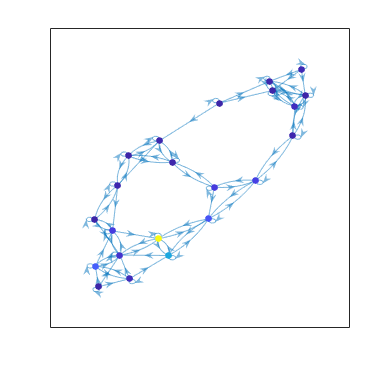

idx = 1;
adj = double(cell2mat(table2array(train_graphs(idx,"Adjacency"))));
feats = cell2mat(table2array(train_graphs(idx,"Features")));
g1 = digraph(adj);
emptytable = table;
plot(g1,"NodeCData",feats,"NodeLabel",emptytable)

An alternate way to show the feature data.

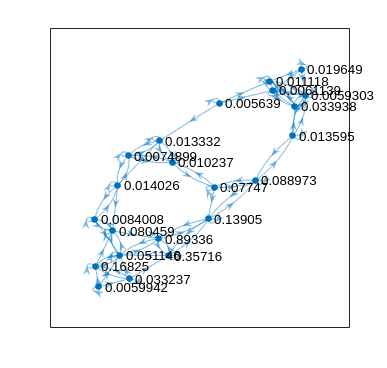

plot(g1,"NodeLabel",feats)

function y= Jet_Table_To_Jet_Tensor(x)
    y = x{:,2:4*35+1}';                
    y = reshape(y,4,35,[]);              
    y = pagetranspose(y);
end